Define system params

close all
clear all
clc
m= 1000; %kg, mass of the vehicle
I=1500; %kgm^2, moment of inertia of the vehicle
a=1.5; %m, distance from the center of mass to the front axle
b=1.5; %m, distance from the center of mass to the rear axle
c=1; % The distance from the center of mass to the left/right side of the tires (y axis)
parameters=[m;I;a;b;c];

V=20;
eps_0=[0;0;0;0.9*V];
lanewidth=3.5;
lanes=3;

MPC

%Sampling time of T_s=0.05
Ts=5e-2;
u_0=zeros(2,1);
[dsys,U,Y,X,DX]=(discreteSS(eps_0,u_0,parameters,Ts));
mpcobj=mpc(dsys);

-->The "PredictionHorizon" property is empty. Assuming default 10.
-->The "ControlHorizon" property is empty. Assuming default 2.
-->The "Weights.ManipulatedVariables" property is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property is empty. Assuming default 1.00000.
   for output(s) y1 y2 and zero weight for output(s) y3 y4 


STEPS:

- Define prediction horizon

mpcobj.PredictionHorizon = 60; %2 sec
mpcobj.ControlHorizon=2; %0.1 Sec

- Constraints on Control (Max Throttle, Max throttle rate of change. Max steering angle,)

mpcobj.ManipulatedVariables(2).RateMin = -0.2*Ts;
mpcobj.ManipulatedVariables(2).RateMax = 0.2*Ts;
mpcobj.ManipulatedVariables(1).RateMin = -pi/10*Ts;
mpcobj.ManipulatedVariables(1).RateMax = pi/10*Ts;

mpcobj.ManipulatedVariables(1).ScaleFactor = 0.2;
mpcobj.ManipulatedVariables(2).ScaleFactor = 2;
mpcobj.OV(2).ScaleFactor=(1/100);

## ;

% # Weights on output vars
% mpcobj.Weights.OutputVariables=[0 30 0 1]; %Weight on x_dot,y_dot,psi and y
% # Nominal operating point
mpcobj.Model.Nominal.X=X;
mpcobj.Model.Nominal.U=U;
mpcobj.Model.Nominal.DX=DX;
mpcobj.Model.Nominal.Y=Y;

- Define the constraints on the output variables

%Type of constraints: E*u+F*y<=G
% # Weights on output vars
mpcobj.Weights.OutputVariables=[0 30 0.1 1]; %Weight on x_dot,y_dot,psi and y
mpcobj.Weights.ManipulatedVariables=[1 1];
%Create obstacle
obstacle=createObstacle();
obstacle=ObstacleGeometry(obstacle);
[E,F,G]=baseConstraints(lanewidth,lanes);
setconstraint(mpcobj, E,F,G,[1;1;0.1]);

% %Terminal constraint
% Y_term=struct('Weight',[0 5 0 0 30 0],'Min',[-10 -10 -10 -10 -lanes*lanewidth/2 0],'Max',[10 10 10 10 lanes*lanewidth/2 inf]);
% U_term=struct('Max',[max_angle maxT maxT maxT maxT]);
% setterminal(mpcobj,Y_term,U_term,mpcobj.PredictionHorizon)
% %Simulate the system
refSpeed=[V;0;0;0];

%Initial conditions
x=eps_0;
u=u_0;
y=dsys.C*eps_0;
egostates=mpcstate(mpcobj);

   Assuming no disturbance added to measured output channel #2.
-->Assuming output disturbance added to measured output channel #4 is integrated white noise.
-->Assuming output disturbance added to measured output channel #3 is integrated white noise.
   Assuming no disturbance added to measured output channel #1.
-->The "Model.Noise" property is empty. Assuming white noise on each measured output.



T=0:Ts:10;

%Vars to store simulation data
predN=[10 20 30 40 50 60];
statesN=zeros(length(predN),length(x),length(T));
inputsN=zeros(length(predN),length(u),length(T));
controllability = zeros(1,length(T));
detected=zeros(1,length(T));
slopes=zeros(1,length(T));
intercepts=zeros(1,length(T));
costs=zeros(1,length(T));
% Simulate the system
period=1;
refsine=@(x) lanewidth*sin(x/V);
opt=mpcmoveopt;
A_ts=zeros(4,4,length(T));
B_ts=zeros(4,2,length(T));

for j=1:length(predN)
        egostates=mpcstate(mpcobj)
    opt=mpcmoveopt;
    opt.PredictionHorizon=predN(j);
    opt.ControlHorizon=2;
    states=zeros(length(x),length(T));
    inputs=zeros(length(u),length(T));
    for i=1:length(T)
        %Update plant states
        [newsys,U,Y,X,DX]=(discreteSS(x,u,parameters,Ts));
        A_ts(:,:,i)=newsys.A;
        B_ts(:,:,i)=newsys.B;

        %Update constraints
        %Update nominal operating point
        newNominal=struct('X',X,'U',U,'DX',DX,'Y',Y);
        measurements=newsys.C*x+newsys.D*u;

        %Detection logic
        detect=ObstacleDetect(x,obstacle);
        detected(i)=detect;
        %     detect=false;
        %Update ref using constraint
        % Uncomment for sine reference
        %FUNCTION for y target here

        [refY,WeightY] = ReferenceUpdate(x,obstacle,detect,lanewidth);
        % opt.OutputWeights=[0 WeightY 0.1 1];
        refSpeed=[0 refY 0 V];

        %Get the optimal control action
        % e=x-refspeed;
        % d_e=e_prev-e;
        % u=kp*e_prop+kd*d_e
        % e_prev=e
        [u,info]=mpcmoveAdaptive(mpcobj, egostates, newsys, newNominal, measurements, refSpeed, [],opt);
        %Time update of the system
        x=egostates.Plant;
        costs(i)=info.Cost;
        %Save the results
        %     K = [B_ts(i), A_ts(i)*B_ts(i), A_ts(i)^2*B_ts(i),A_ts(i)^3*B_ts(i)];
        %     controllability(:,i) = rank(K);
        controllability(:,i)=rank(ctrb(A_ts(:,:,i),B_ts(:,:,i)));
        states(:,i)=x;
        inputs(:,i)=u;
    end
    statesN(j,:,:)=states;
    inputsN(j,:,:)=inputs;
end

MPCSTATE object with fields
          Plant: [0 0 0 18]
    Disturbance: [0 0]
          Noise: [1×0 double]
       LastMove: [0 0]
     Covariance: [6×6 double]

MPCSTATE object with fields
          Plant: [0 0 0 18]
    Disturbance: [0 0]
          Noise: [1×0 double]
       LastMove: [0 0]
     Covariance: [6×6 double]

MPCSTATE object with fields
          Plant: [0 0 0 18]
    Disturbance: [0 0]
          Noise: [1×0 double]
       LastMove: [0 0]
     Covariance: [6×6 double]

MPCSTATE object with fields
          Plant: [0 0 0 18]
    Disturbance: [0 0]
          Noise: [1×0 double]
       LastMove: [0 0]
     Covariance: [6×6 double]

MPCSTATE object with fields
          Plant: [0 0 0 18]
    Disturbance: [0 0]
          Noise: [1×0 double]
       LastMove: [0 0]
     Covariance: [6×6 double]

MPCSTATE object with fields
          Plant: [0 0 0 18]
    Disturbance: [0 0]
          Noise: [1×0 double]
       LastMove: [0 0]
     Covariance: [6×6 double]



Plot results

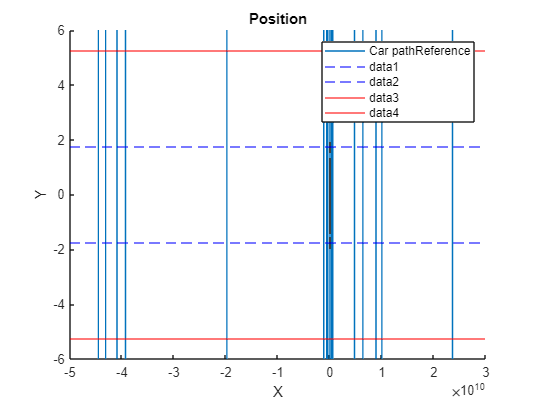

figure
hold on
plot(states(1,:),states(2,:))
% plot(states(1,:),refsine(states(1,:)))
legend(['Car path','Reference'])
% Plot obstacle
rectangle(Position=[obstacle.rrX,obstacle.rrY,obstacle.Length,obstacle.Width])
rectangle('Position',[obstacle.rrSafeX,obstacle.rrSafeY,obstacle.Length+2*obstacle.safeDistanceX,obstacle.Width+2*obstacle.safeDistanceY],'LineStyle','--')
yline(lanewidth/2,'b--')
yline(-lanewidth/2,'b--')
yline(-lanewidth*lanes/2,'r')
yline(lanewidth*lanes/2,'r')
% xlim([0 500])
ylabel('Y')
xlabel('X')
title('Position')

ylim([-6 6])
hold off

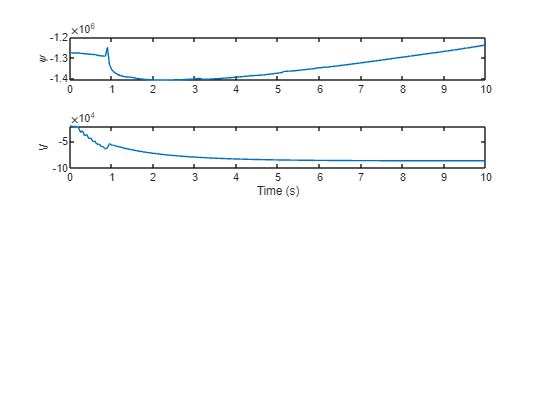

figure
subplot(4,1,1)
plot(T,states(3,:))
ylabel('\psi')
subplot(4,1,2)
plot(T,states(4,:))
ylabel('V')
xlabel('Time (s)')

Plot input

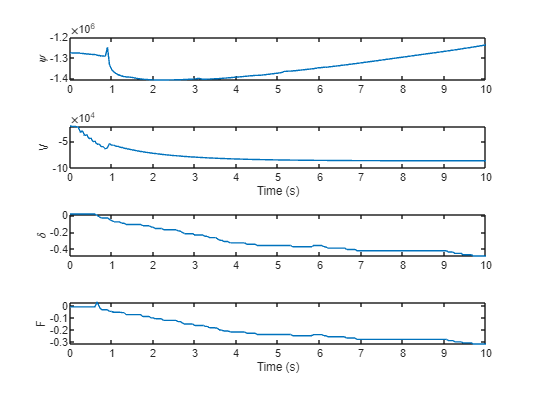

subplot(4,1,3)
plot(T,inputs(1,:))
ylabel('\delta')
subplot(4,1,4)
plot(T,inputs(2,:))
ylabel('F')
xlabel('Time (s)')

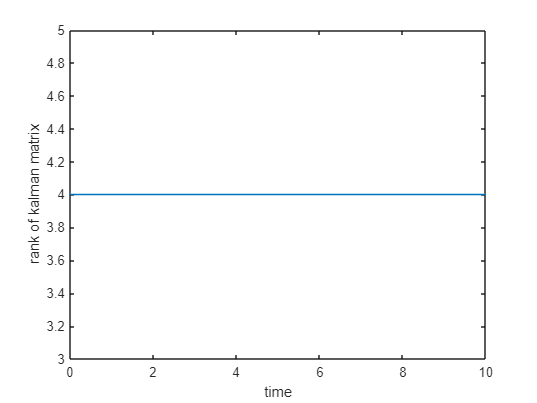

%
%
figure
plot(T,controllability(1,:));
ylabel('rank of kalman matrix');
xlabel('time');

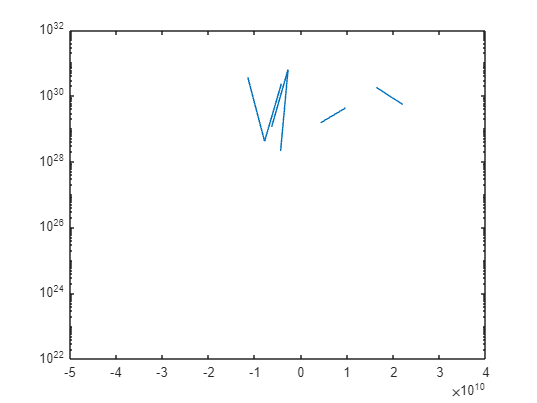

figure
semilogy(states(1,:),costs)

% ylim([0 100])
% xlim([0 100])